%计算考虑化学作用后的双腔室二锁体系
clear all

y1=[];
y2=[];
Plock=[];
Vlock=[];
Vopen=[];

%笼腔长度等于多少个sigma(o)吗，
l2=2;


for l1=2.1:0.02:4.5
%计算锁死所占成分
    fun1 = @(x1) P(x1).^2.* P(l2).^2.*P(l1-x1).^2.*P(x1-l2);
    V_lock = 1*integral(fun1,l2,l1);
    
%计算开放所占成分
    fun2 = @(x1) P(l1).^2.* P(l2).^2.*P(x1-l1-l2).^2.*P(2*l1+l2-x1);
    V_open = 1*integral(fun2,l1+l2,2*l1+l2);
    
    P_lock = V_lock/(V_lock + V_open)  %计算锁死所占比例
    Plock=[Plock,P_lock];
end

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 0

P_lock = 6.6690e-308

P_lock = 4.6931e-258

P_lock = 1.5111e-216

P_lock = 6.3749e-182

P_lock = 5.4584e-153

P_lock = 8.9454e-129

P_lock = 1.7701e-108

P_lock = 1.9249e-91

P_lock = 4.0131e-77

P_lock = 4.5032e-65

P_lock = 6.3919e-55

P_lock = 2.3308e-46

P_lock = 3.9330e-39

P_lock = 5.0113e-33

P_lock = 7.2527e-28

P_lock = 1.6770e-23

P_lock = 8.2429e-20

P_lock = 1.0946e-16

P_lock = 4.8034e-14

P_lock = 8.2540e-12

P_lock = 6.4120e-10

P_lock = 2.5369e-08

P_lock = 5.6711e-07

P_lock = 7.8067e-06

P_lock = 7.1179e-05

P_lock = 4.5717e-04

P_lock = 0.0022

P_lock = 0.0080

P_lock = 0.0236

P_lock = 0.0567

P_lock = 0.1137

P_lock = 0.1933

P_lock = 0.2859

P_lock = 0.3784

P_lock = 0.4607

P_lock = 0.5284

P_lock = 0.5814

P_lock = 0.6213

P_lock = 0.6506

P_lock = 0.6715

P_lock = 0.6857

P_lock = 0.6948

P_lock = 0.6998

P_lock = 0.7016

P_lock = 0.7008

P_lock = 0.6979

P_lock = 0.6934

P_lock = 0.6875

P_lock = 0.6806

P_lock = 0.6729

P_lock = 0.6646

P_lock = 0.6560

P_lock = 0.6471

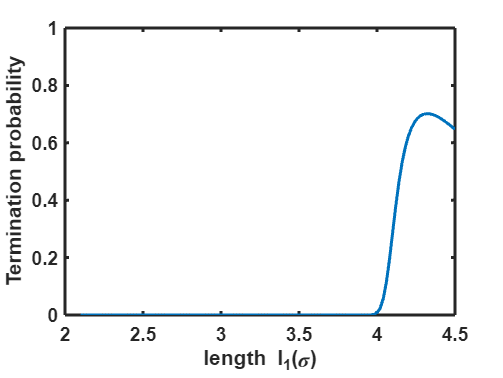



x=2.1:0.02:4.5;
plot(x,Plock,'LineWidth',1.5)

ylim([0 1]);
set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('length l_1(\sigma)','FontName','arial','FontWeight','bold'); 
ylabel('Termination probability','FontName','arial','FontWeight','bold');

function a= E(r) %定义特定的势能函数E(r)
    e=4120;
    o=1;%计算的其实是o/r
    a=4.*e.*(((r/o).^(-12))-((r/o).^(-6)));
end

function b=P(r) %定义相应的概率分布函数P(r)
    b=exp(-E(r)/(8.31*298));
end


